# 1. Repàs de la segmentació per watershed

clear
orig = imread('cornea.tif');
figure, imshow(orig);
ee = strel('disk',1); 
% calculem el gradient. Ho podem fer morfològic
grad=imsubtract(imdilate(orig,ee),imerode(orig,ee));
figure,imshow(grad),title('gradient')
% mirem de segmentar les cèlules fent watershed sobre la imatge gradient
segm=watershed(grad);
figure,imshow(segm), title('segmentacio per watershed')
% resultat sobresegmentat. Cal treballar amb markers
%% marker-controlled watershed
% usarem els màxims regionals com a markers de les cèlules
% la imatge és molt sorollosa. Cal filtrar abans
ee=strel('disk',2);
filt=imopen(imclose(orig,ee),ee); %filtre OC
figure,imshow(filt)
rm=imregionalmax(filt);
figure,imshow(rm),title('maxims regionals')
% Usem els maxims regionals com a markers pel watershed
segm=watershed(imimposemin(grad,rm));
figure,imshow(segm),title('watersehed amb markers')


**Feu un overlay, en color, dels contorns obtinguts sobre la imatge original. Us sembla correcta la segmentació? O ens em oblidat alguna cosa ?**

La segmentació es incorrecta. Porque al coger maximos regionales tambien coges como marka cosas que no son celula.

origR = orig;
origG = orig;
origB = orig;
origR(segm == 0) = 255;
origG(segm == 0) = 0;
origB(segm == 0) = 0;
result = cat(3,origR,origG,origB);
imshow(result)


## Cal trobar un marker pel fons

% L'obtenim fent el watershed de la imatge negada.
%Usem com a markers els mateixos maxims d'abans
Norig=imcomplement(orig);
figure,imshow(Norig),title('imatge negada')
fons=watershed(imimposemin(Norig,rm));
figure,imshow(fons),title('marker del fons')
% Fem una imatge de markers a partir de les celules i del fons
markers=~fons|rm;
figure,imshow(markers),title('marques')
% fem el watershed amb les noves marques
segm=watershed(imimposemin(grad,markers));
figure,imshow(segm),title('segmentacio final')

Dibuixeu de nou el resultat en overlay

origR = orig;
origG = orig;
origB = orig;
origR(segm == 0) = 255;
origG(segm == 0) = 0;
origB(segm == 0) = 0;
result = cat(3,origR,origG,origB);
imshow(result), title('watershed 1')
%% hem perdut alguna cèlula.
% Aixó és degut a que alguns markers de les celules es toquen amb el marker del fons (veure imatge ‘markers’)

Utilitzeu operacions morfològiques sobre les imatges de marques per a evitar que els markers estoquin. Genereu una nova imatge de marques.

Segmenteu la imatge amb watershed usant les noves marques i mostreu el resultat en overlay.

ee = strel('square',2)
rm = imerode(rm,ee);
markers=~fons|rm;
figure,imshow(markers),title('marques')
% fem el watershed amb les noves marques
segm=watershed(imimposemin(grad,markers));
figure,imshow(segm),title('segmentacio final')

Dibuixeu de nou el resultat en overlay

origR = orig;
origG = orig;
origB = orig;
origR(segm == 0) = 255;
origG(segm == 0) = 0;
origB(segm == 0) = 0;
result = cat(3,origR,origG,origB);
imshow(result),  title('watershed 2')

# 2. Segmentació per clustering. K-means

clear
im = imread('pepper.png');
[MAXFILA MAXCOL chan]= size(im)

MAXFILA = 512

MAXCOL = 512

chan = 3

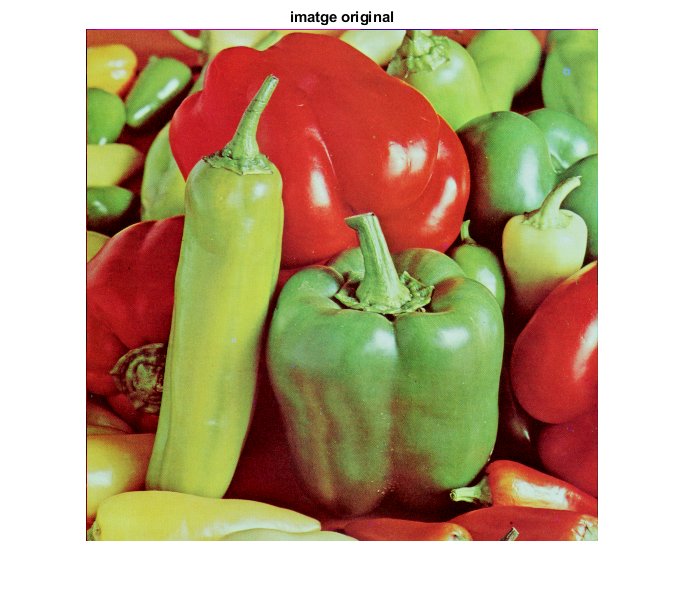

figure,imshow(im),title('imatge original');

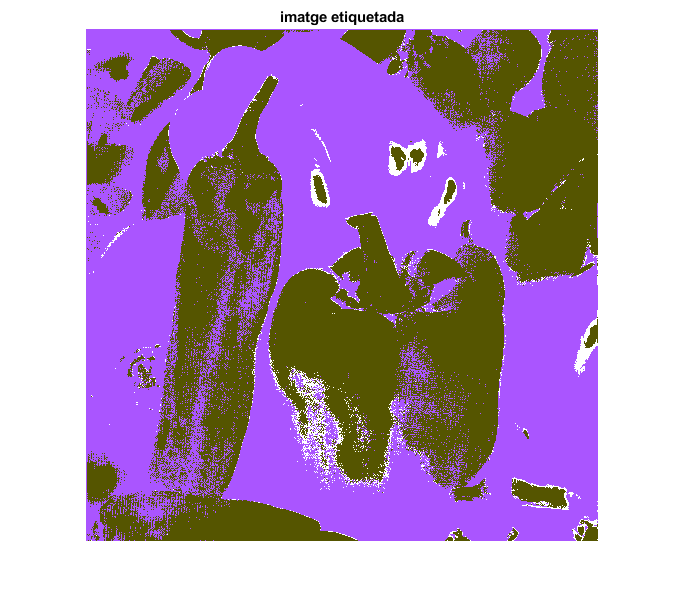

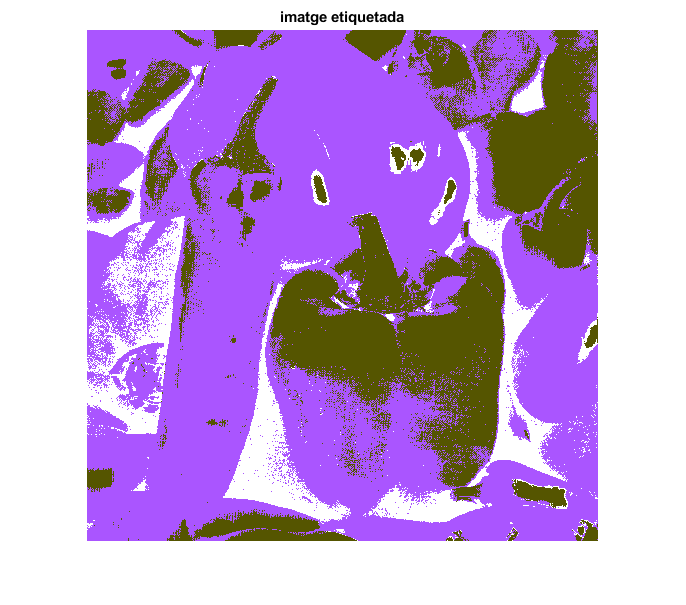

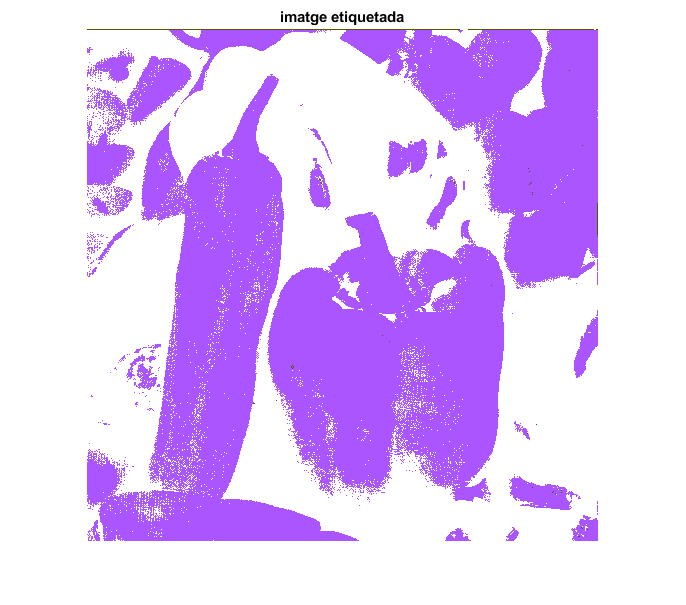

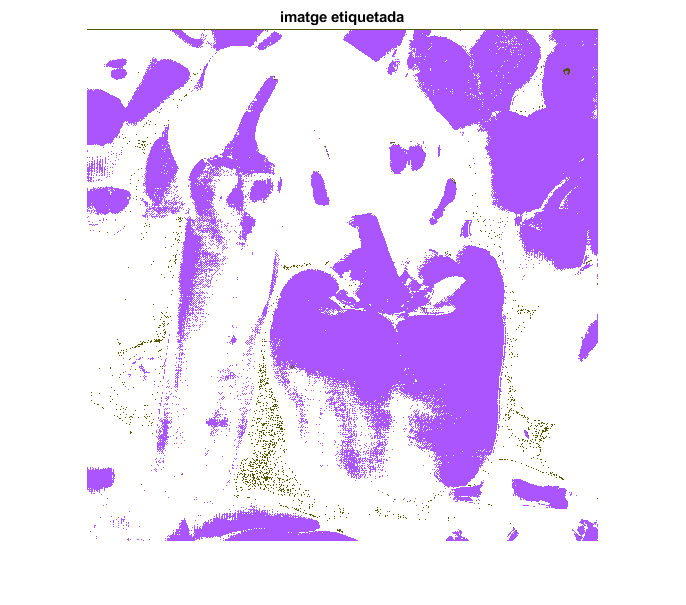

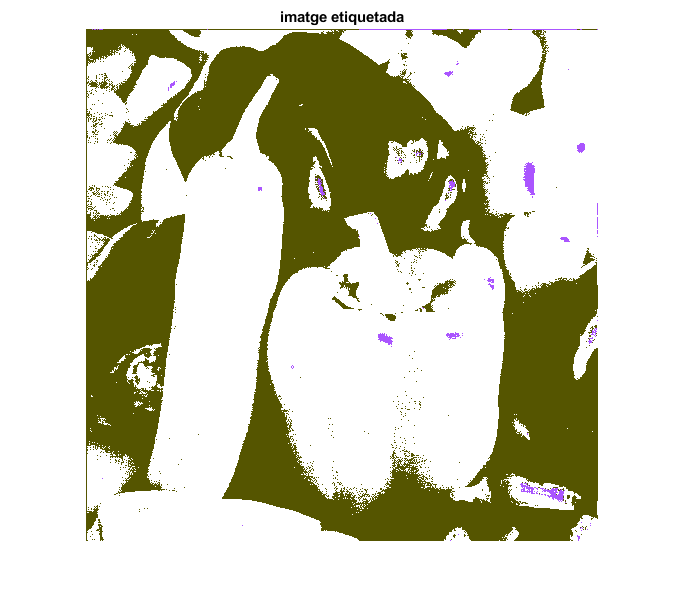

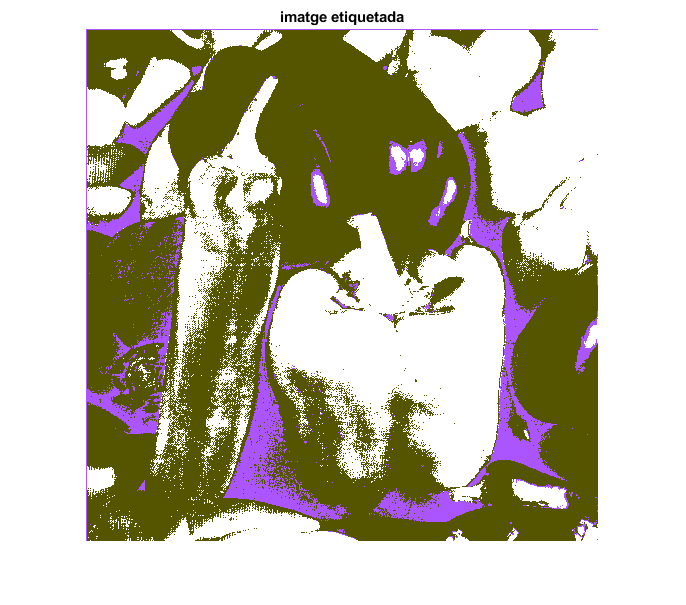

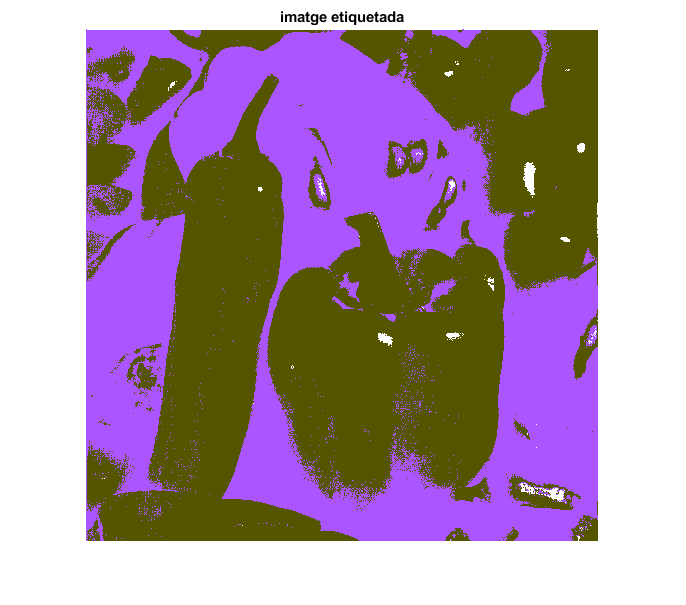

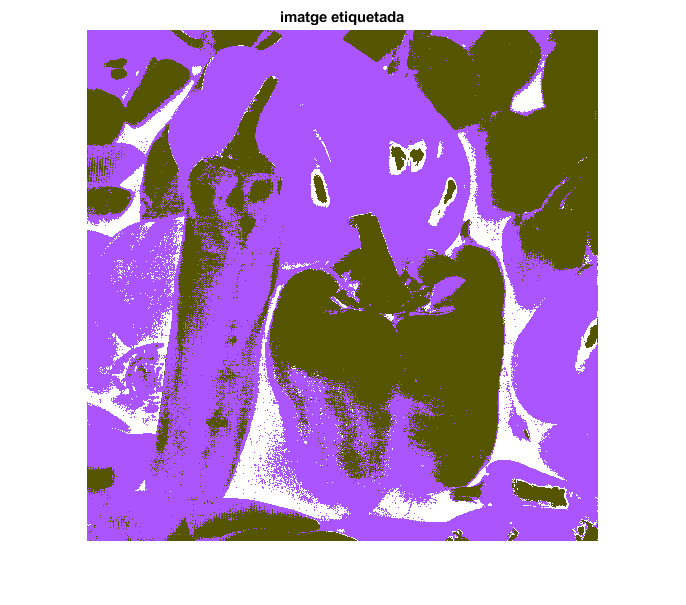

% la segmentarem per color. Treballarem en l’espai Hue-Sat
hsv=rgb2hsv(im);
hs=hsv(:,:,1:2);
h = hsv(:,:,1);
s = hsv(:,:,1);
vect=reshape(hs,MAXFILA*MAXCOL,2); % feature vector. 2 features per píxel
Nclusters=3; %vermell, verd, i negre
% Usarem la funció kmeans amb distancia citiblock
%[cluster_idx, cluster_center] = kmeans(vect,Nclusters,'distance','cityblock');
[cluster_idx] = kmeans(vect, Nclusters, 20);

eti=reshape(cluster_idx,MAXFILA,MAXCOL);
figure,imshow(eti,[]),colormap(colorcube), title('imatge etiquetada')

Algo no va. Els pebrots vermells queden mal segmentats. Què està passant ?

El hue és un angle. És cíclic. Píxels vermells amb hue molt similars queden a banda i banda de l’espai hue-sat per culpa del pas per zero.

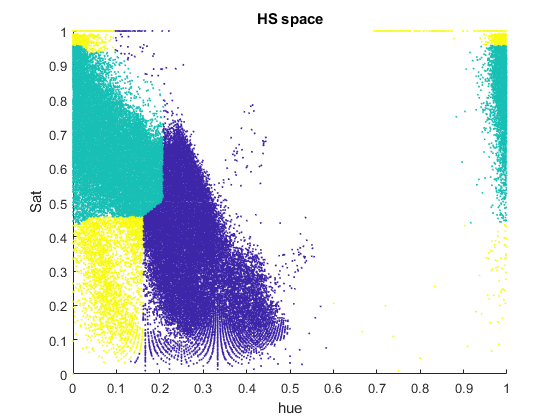

% Representem els píxels en l’espai hue-sat
figure,scatter(vect(:,1),vect(:,2),1,cluster_idx);
xlabel('hue');ylabel('Sat')
title('HS space')

% El hue és un angle. És cíclic.
% Píxels vermells amb hue molt similars queden a banda i banda de l’espai hue-sat per culpa del pas per zero.



%Error
calculate_mean([2 9 9], 10)

function [cluster_idx] = kmeans(points, Nclusters, Niteraciones)
    [rows columns] = size(points);
    cluster = zeros(Nclusters,2)-1;
    %calculate inicial center of the clusters
    for i = 1:Nclusters
        j = fix(rand(1)*(rows-1))+1;
        x = points(j,1);
        y = points(j,2);
        while (ismember(x,cluster(:,1)) & ismember(y,cluster(:,2)))
            j = fix(rand(i)*(rows-1))+1;
            x = points(j,1);
            y = points(j,2);
        end
        cluster(i,1) = x;
        cluster(i,2) = y;
    end
    cluster_final = cluster;
    [cluster ,cluster_idx] = cluster_iteration(points, cluster, Nclusters);
    i = 0;
    while (~isequal(cluster_final, cluster) && i <Niteraciones)
        i = i +1;
        [cluster ,cluster_idx] = cluster_iteration(points, cluster, Nclusters);
        %eti=reshape(cluster_idx,512,512);
        %figure,imshow(eti,[]),colormap(colorcube), title('imatge etiquetada')
    end
    
end
function  [point] = calculate_mean(points,range)
    point_sin = sum(sin((points*2*pi)/range));
    point_cos = sum(cos((points*2*pi)/range));
    
    point_sin = point_sin/length(points);
    point_cos = point_cos/length(points);
    point = atan(point_sin/point_cos);
    if (point < 0)
        point = 2*pi + point;
    end
    point = (point*range)/(2*pi);
end


function  [cluster ,cluster_idx] = cluster_iteration(points, cluster, Nclusters)
    [rows columns] = size(points);
    cluster_idx = zeros(rows,1);
    for i = 1:rows
        best_cluster = 1;
        x = abs(cluster(1,1) - points(i,1));
        y = abs(cluster(1,2) - points(i,2));
        best_distance = min( x ,(1-x)) + min(y, (1-y));
        for j = 2:Nclusters
            x = abs(cluster(j,1) - points(i,1));
            y = abs(cluster(j,2) - points(i,2));
            distance = min( x ,(1-x)) + min(y, (1-y));
            if distance < best_distance 
                best_cluster = j;
                best_distance = distance;
            end
        end
        cluster_idx(i) = best_cluster;
    end
    
    points_aux_x = points(:,1);
    points_aux_y = points(:,2);
    for cluster_number = 1:Nclusters
        points_x = points_aux_x(cluster_idx ==  cluster_number);
        points_y = points_aux_y(cluster_idx ==  cluster_number);
        [cluster_x] = calculate_mean(points_x, 1);
        [cluster_y] = calculate_mean(points_y, 1);
        cluster(cluster_number,1) = cluster_x;
        cluster(cluster_number,2) = cluster_y;
    end
end